syms omega t A B

x = A*sin(omega*t)

$$x = A\,\sin\left(\omega \,t\right)$$


y = B*cos(omega*t)-1

$$y = B\,\cos\left(\omega \,t\right)-1$$


xdot = diff(x,t)

$$xdot = A\,\omega \,\cos\left(\omega \,t\right)$$


ydot = diff(y,t)

$$ydot = -B\,\omega \,\sin\left(\omega \,t\right)$$


x_dotdot = diff(x,t,2)

$$x\_dotdot = -A\,\omega^{2}\,\sin\left(\omega \,t\right)$$


y_dotdot = diff(y,t,2)

$$y\_dotdot = -B\,\omega^{2}\,\cos\left(\omega \,t\right)$$

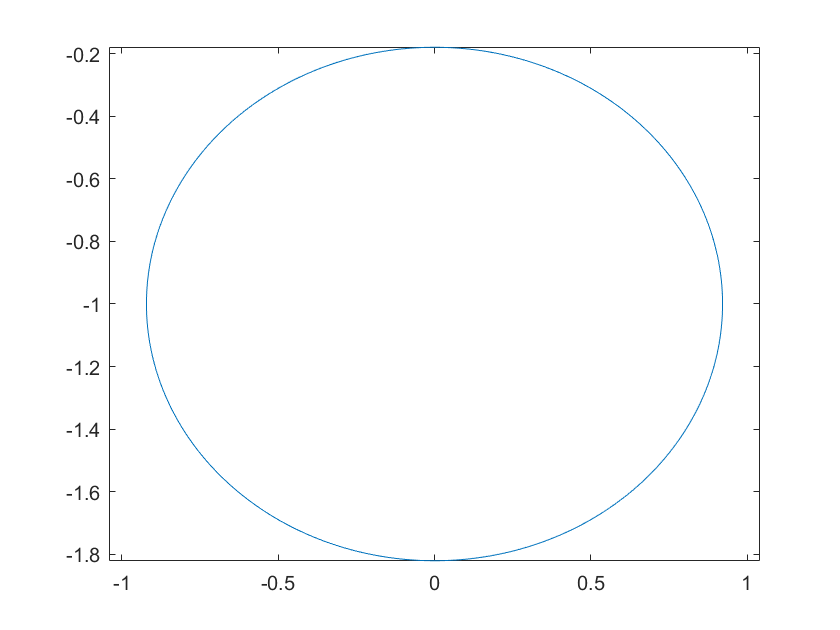


theta = 0:0.01:21;
x_test = (1/1.0865)*sin(0.3*theta);
y_test = (1/1.2191)*cos(0.3*theta)-1;

plot(x_test, y_test)
axis equal

## Polyline trajectory

### Type 1 - Vertical M

clearvars
close all

X = 0:0.01:25;
Y = 0:0.01:25;

for t=0:0.01:25
    index = uint64(t*100 + 1);
    if t <= 5
        X(index) = 0.5*(1/5)*t;
        Y(index) = 0.5*0;
    elseif t>5 && t<=10
        X(index) = -0.5*(1/5)*(t-5) + 0.5*1;
        Y(index) = 0.5*(1/5)*(t-5);
    elseif t>10 && t<=15
        X(index) = 0.5*(1/5)*(t-10);
        Y(index) = 0.5*(1/5)*(t-5);
    elseif t>15 && t<=20
        X(index) = -0.5*(1/5)*(t-15) + 0.5*1;
        Y(index) = 0.5*2;
    else
        X(index) = 0.5*0;
        Y(index) = 0.5*2;
    end
end

figure
plot(X,Y)
axis equal

### Type2 - Square Horitzontal signal

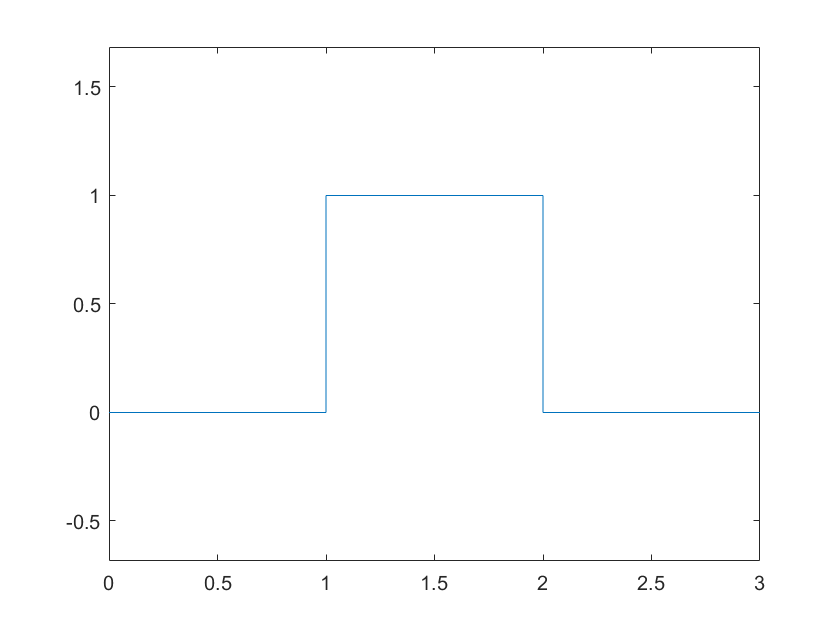

clearvars
close all

X = 0:0.01:25;
Y = 0:0.01:25;

for t=0:0.01:25
    index = uint64(t*100 + 1);
    if t <= 5
        X(index) = (1/5)*t;
        Y(index) = 0;
    elseif t>5 && t<=10
        X(index) = 1;
        Y(index) = (1/5)*(t-5);
    elseif t>10 && t<=15
        X(index) = (1/5)*(t-10)+1;
        Y(index) = 1;
    elseif t>15 && t<=20
        X(index) = 2;
        Y(index) = -(1/5)*(t-15)+1;
    elseif t>20 && t<=25
        X(index) = (1/5)*(t-20)+2;
        Y(index) = 0;
    else
        X(index) = 3;
        Y(index) = 0;
    end
end

figure
plot(X,Y)
axis equal